Con la ayuda de los algoritmos desarrollados y de la GUI construida se ubica la ruta seleccionada con la orientación indicada dentro del espacio diestro del robot. 

Aparitr de la matriz de rotación se ubica la trayectoria normal al vector deseado y las coordenadas dx, dy y dz representan la ubicación del centro de la trayectoria para que quede ubicada dentro del espacio diestro del robot.

clear; clc; close all;
%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];
% Desplazamiento
dx = 500;
dy = 0;
dz = 400;

Se define un conjunto de puntos equidistantes que pertenecen a la ruta (viapoints). El eje z de la herramienta se mantiene perpendicular al plano que contiene la ruta. 

Estimando el perímetro de la ruta se establece la distancia máxima entre los viapoints para generar mínimo 60 puntos en toda la trayectoria.

H=700;
a = 0.18*H; %distancia en x
b = 0.1*H;  %distancia en y
c = 0.08*H; %centro en y de los semicirculos
r = 0.02*H; %radio
dis_max = (a*4+c*4+2*pi*r)/60

dis_max = 13.5994

De esta manera se elige un delta de distancia menor al límite, asegurando así la cantidad de puntos propuesto para toda la trayectoria.

delta = 10;
%%Ruta 1
x = -a:delta:a;
len = size(x);
y = -b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = R1;

%%Ruta 2
t = 3*pi/2:delta/r:2*pi;
x = r*cos(t)+a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 3
y = -c:delta:c;
len = size(y);
x = (a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 4
t = 0:delta/r:pi/2;
x = r*cos(t)+a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 5
x = a:-delta:-a;
len = size(x);
y = b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 6
t = pi/2:delta/r:pi;
x = r*cos(t)-a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 7
y = c:-delta:-c;
len = size(y);
x = -(a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];

%%Ruta 8
t = pi:delta/r:3*pi/2;
x = r*cos(t)-a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];

traye = [traye,R1];

Finalmente, se aplican los parámetros de rotación y desplazamiento mencionados anteriormente.

% Rotacion y dezplazamiento de la trayectoria
len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = dx + traye(1,:);
traye(2,:) = dy + traye(2,:);
traye(3,:) = dz + traye(3,:);

plot3(traye(1,:),traye(2,:),traye(3,:))
xlim([-100 700])
ylim([-200 200])
zlim([0 900])
hold on

Para calcular las configuraciones correspondientes a cada viapoint se crea el robot con el Toolbox de Peter Corke. Adicionalmente se presentan gráficas de cada ángulo de articuación al recorrer la ruta. 

l0 = 350; l1 = 150; l2 = 250+75; l3 = 450;l4 = 80;
ws= [-100 700 -200 200 0 900];
plot_options = {'workspace',ws,'scale',1,'view',[-16 28], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha',     0,'a',   0, 'd',  l0,'offset',   0, 'qlim',        [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha',  pi/2,'a',  l1, 'd',   0,'offset',pi/2, 'qlim',       [-5*pi/6 7*pi/36],   'modified');
L(3) = Link('revolute'  ,'alpha',     0,'a',  l2, 'd',   0,'offset',   0, 'qlim',    [-17*pi/36 47*pi/36],   'modified');
L(4) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',  l3,'offset',   0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',   0, 'qlim',        [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',   0,'offset',   0, 'qlim',            [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
syms theta1 theta2 theta3 theta4 theta5 theta6
MTH01 = L(1).A(theta1);
MTH12 = L(2).A(theta2);
MTH23 = L(3).A(theta3);
MTH34 = L(4).A(theta4);
MTH45 = L(5).A(theta5);
MTH56 = L(6).A(theta6);
MTH6T = Robot.tool;
MTH02 = MTH01*MTH12;
MTH03 = MTH02*MTH23;
MTH04 = MTH03*MTH34;
MTH05 = MTH04*MTH45;
MTH06 = MTH05*MTH56;
MTH0T = MTH06*MTH6T;

Posteriormente, se evalua en la posición de "home" la matriz de transformación homogenea de la base a la herramienta del robot para así determinar la matriz de rotación base. Además, se aplica una rotación adicional alrededor del eje "y" para así asegurar la orientación solicitada del eje z de la herramienta. Finalmente, se procede a calcular la cinemática inversa con cada punto de la trayectoria creada, manteniendo la orientación del TCP constante en todo el recorrido.

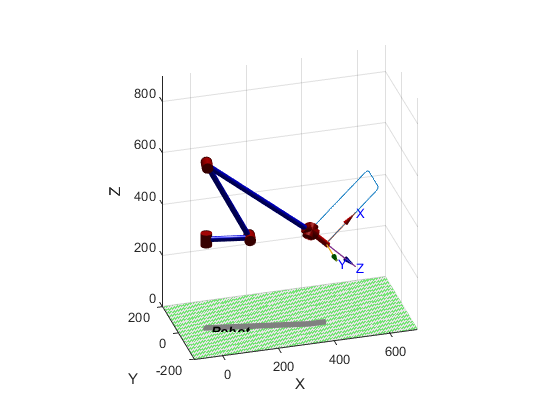

MTH0T = double(subs(MTH0T,[theta1,theta2,theta3,theta4,theta5,theta6],[0,0,0,0,0,0]));
R = tr2rt(MTH0T)*roty(-pi/4);
R = r2t(R);
for i=1:size(traye,2)
    t_act=traye(:,i);
    T = transl(t_act)*R;    
    q_act = Robot.ikunc(T);    
    if i==1
        q = q_act;
    else               
        q = [q;q_act];
    end   
    t_pas = t_act;
    q_pas = q_act;
end
Robot.plot(q)
view([-16 28])

Al terminar de realizar la trayectoria se obtienen los siguientes perfiles de posición ángular de cada articulación.

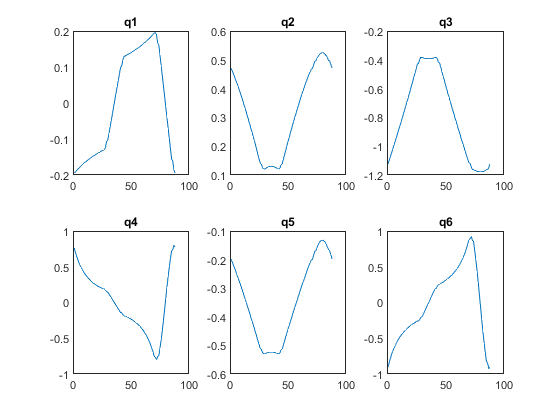

figure()
for i=1:6
    subplot(2,3,i)
    plot(q(:,i))
    title((sprintf('q%d', i)))
end

Finalmente, se calculan las velocidades en cada viapoint de manera que la herramienta recorra la ruta a una velocidad de 500 mm/s. 

Con las MTH de cada articulación respecto a la base, se genera el Jacobiano geométrico que se utilizará para mantener la velocidad del TCP en el valor deseado.

J1 = [cross(MTH01(1:3,3),(MTH0T(1:3,4)-MTH01(1:3,4)));MTH01(1:3,3)];
J2 = [cross(MTH02(1:3,3),(MTH0T(1:3,4)-MTH02(1:3,4)));MTH02(1:3,3)];
J3 = [cross(MTH03(1:3,3),(MTH0T(1:3,4)-MTH03(1:3,4)));MTH03(1:3,3)];
J4 = [cross(MTH04(1:3,3),(MTH0T(1:3,4)-MTH04(1:3,4)));MTH04(1:3,3)];
J5 = [cross(MTH05(1:3,3),(MTH0T(1:3,4)-MTH05(1:3,4)));MTH05(1:3,3)];
J6 = [cross(MTH06(1:3,3),(MTH0T(1:3,4)-MTH06(1:3,4)));MTH06(1:3,3)];
Jsim = [J1,J2,J3,J4,J5,J6];

Debido a que el Jacobiano depende de la posición actual del robot, se debe realizar el cálculo numérico del mismo cada vez que el robot actualiza su posición. De la misma forma, se deben calcular en cada punto de la trayectoria las velocidades articulares sabiendo que se desea una velocidad contante del TCP. Para asegurar esto, el vector de velocidad lineal objetivo se encuentra en la misma dirección y sentido del vector director que va del punto actual al punto siguiente de la trayectoria pero su norma es igual a la velocidad deseada. Las velocidades angulares de la herramienta se mantienen constantes en 0.

for i=1:size(traye,2)
    t_act=traye(:,i);
    T = transl(t_act)*R;    
    q_act = Robot.ikunc(T);    
    if i==1
        q = q_act;
    else
        J = double(subs(Jsim,[theta1,theta2,theta3,theta4,theta5,theta6],q_pas));
        vecT=(t_act-t_pas);
        vecT=vecT/norm(vecT)*500;
        q_dot_act = (J^-1*[vecT;0;0;0])';
        if i==2
            q_dot = q_dot_act;
        else
            q_dot = [q_dot;q_dot_act];
        end        
        q = [q;q_act];
    end   
    t_pas = t_act;
    q_pas = q_act;
end

En las siguientes gráficas se muestra la velocidad de cada articulación.

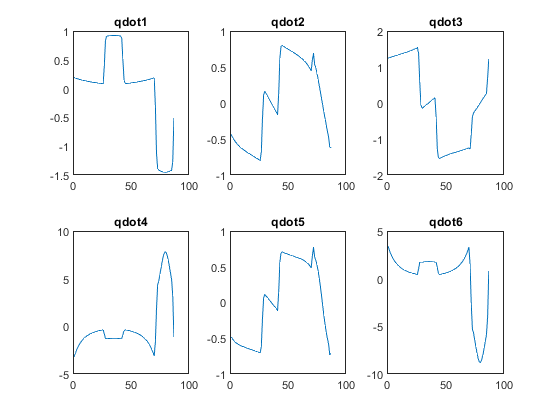

figure()
for i=1:6
    subplot(2,3,i)
    plot(q_dot(:,i))
    title((sprintf('qdot%d', i)))
end